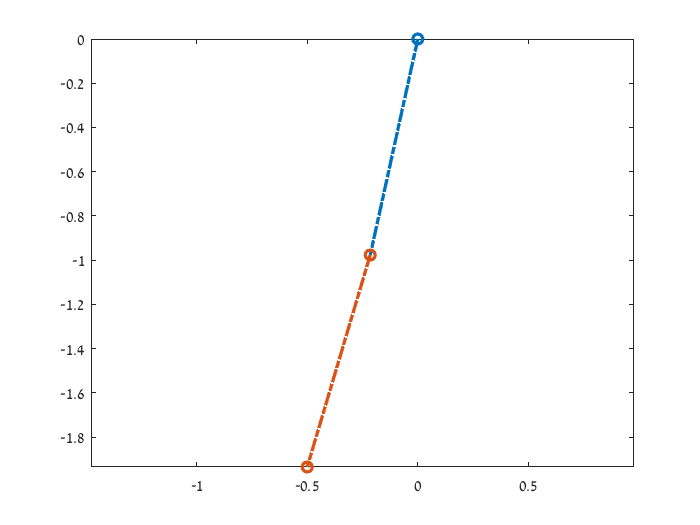

% initilaze
h = 0.1;  %time -step
time_span = [0 10];  % set the interval of t big enough to assure collide  
y0 = [pi/4 1 0 0];   % set the intial value for y0

[t,y] = MY_RK4_event(@(t,y) My_DoublePendulum(t,y) ,h,time_span,y0);

l1 = 1; l2 = 1; %lengths in the pendulum
xdraw = [l1*sin(y(:,1)), l1*sin(y(:,1))+l2*sin(y(:,2))]; % caluclate joints x position
ydraw = [-l1*cos(y(:,1)),-l1*cos(y(:,1))-l2*cos(y(:,2))]; % caluclate joints y position

%plot the first handle
plot([0 xdraw(end,1)],[0 ydraw(end,1)],'marker','O','LineWidth',2,'LineStyle','-.');
hold on
%plot the second handle
plot([xdraw(end,1) xdraw(end,2)],[ydraw(end,1) ydraw(end,2)],'marker','O','LineWidth',2,'LineStyle','-.');
axis equal
hold off

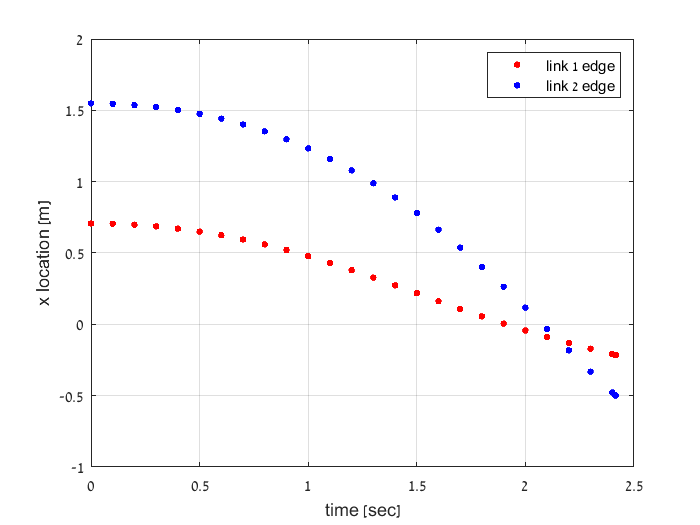

figure
plot(t,xdraw(:,1),'.r','MarkerSize',10) % plot first link edge poition marked 
hold on
plot(t,xdraw(:,2),'.b','MarkerSize',10) % plot secound link edge poition marked 
grid on ;hold off; legend ('link 1 edge','link 2 edge');xlabel ('time [sec]');ylabel('x location [m]')